# 2|4 DOF悬架的路面模型

%% Generate ISO 8608 Road (Spatial Domain)
clc; clear;

% ===== ISO 参数 =====
Gq_n0 = 64e-6;   % C级路面
n0    = 0.1;
w     = 2;

% ===== 空间参数 =====
L  = 500;        % 路面长度 (m) 够长，防止跑飞
dx = 0.01;       % 空间分辨率
N  = round(L/dx);

x = (0:N-1)' * dx;

% ===== 频域 =====
df = 1 / L;
n  = (1:N/2-1)' * df;

Gq  = Gq_n0 * (n / n0).^(-w);
phi = 2*pi*rand(size(n));
A   = sqrt(2 * Gq * df);

Z = zeros(N,1);
Z(2:N/2)       = A .* exp(1i*phi);
Z(N/2+2:end)   = conj(flipud(Z(2:N/2)));

z_x = real(ifft(Z)) * N;


% ===== 保存到工作区 =====
road.x   = x;
road.z   = z_x;
road.dx  = dx;
road.L   = L;

% 获取当前时间并格式化
currentTime = datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss');
disp(['当前时间：', char(currentTime)]);

当前时间：2026-02-04 19:10:27


# 7DOF悬架的路面模型

%% Generate ISO 8608 Road (Spatial Domain)
clc; clear;

% ===== ISO 参数 =====
Gq_n0 = 64e-6;   % C级路面
n0    = 0.1;
w     = 2;

% ===== 空间参数 =====
L  = 500;        % 路面长度 (m) 够长，防止跑飞
dx = 0.01;       % 空间分辨率
N  = round(L/dx);

x = (0:N-1)' * dx;

% ===== 频域 =====
df = 1 / L;
n  = (1:N/2-1)' * df;

Gq  = Gq_n0 * (n / n0).^(-w);
phi = 2*pi*rand(size(n));
A   = sqrt(2 * Gq * df);

Z = zeros(N,1);
Z(2:N/2)       = A .* exp(1i*phi);
Z(N/2+2:end)   = conj(flipud(Z(2:N/2)));

z_x = real(ifft(Z)) * N;


% ===== 保存到工作区 =====
road.x   = x;
road.z   = z_x;
road.dx  = dx;
road.L   = L;

% ======= 前面都是一样的 ======= %
% 左轮路面
road.z_L = road.z;

% 独立随机路面（同 PSD）
z_ind = road.z(randperm(length(road.z)));

% 右轮路面（相关合成）
rho = 0.8;   % 左右轮相关系数
road.z_R = rho * road.z_L + sqrt(1 - rho^2) * z_ind;

# 数据分析与绘图

## 2-DOF Suspension Data Analysis

% 已知变量：
% t, zs, zu, zs_dot, zu_dot

clc;
simout = sim("suspension2DOF.slx")

simout =   Simulink.SimulationOutput:

                   tout: [10001x1 double] 
                     zs: [10001x1 double] 
                 zs_dot: [10001x1 double] 
                     zu: [10001x1 double] 
                 zu_dot: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t = simout.tout;
zu = simout.zu;
zs = simout.zs;
zu_dot = simout.zu_dot;
zs_dot = simout.zs_dot;

dt = t(2) - t(1);
fs = 1 / dt;
N  = length(t);

%% ===== 1. 车身加速度（舒适性核心指标） =====
zs_ddot = gradient(zs_dot, dt);   % 数值微分

% RMS 加速度
az_rms = sqrt(mean(zs_ddot.^2));

fprintf('簧上质量垂向加速度 RMS = %.4f m/s^2\n', az_rms);

簧上质量垂向加速度 RMS = 1.2609 m/s^2



%% ===== 2. 悬架动挠度分析 =====
susp_defl = zs - zu;   % 悬架行程

defl_rms  = sqrt(mean(susp_defl.^2));
defl_max  = max(abs(susp_defl));

fprintf('悬架动挠度 RMS = %.4f m\n', defl_rms);

悬架动挠度 RMS = 0.0130 m


fprintf('悬架动挠度 最大值 = %.4f m\n', defl_max);

悬架动挠度 最大值 = 0.0573 m



%% ===== 3. 轮胎动载等效指标 =====
% 若无轮胎刚度，可先用簧下加速度作为接地性等效指标
zu_ddot = gradient(zu_dot, dt);

zu_acc_rms = sqrt(mean(zu_ddot.^2));
fprintf('簧下质量加速度 RMS（接地性指标）= %.4f m/s^2\n', zu_acc_rms);

簧下质量加速度 RMS（接地性指标）= 21.1701 m/s^2


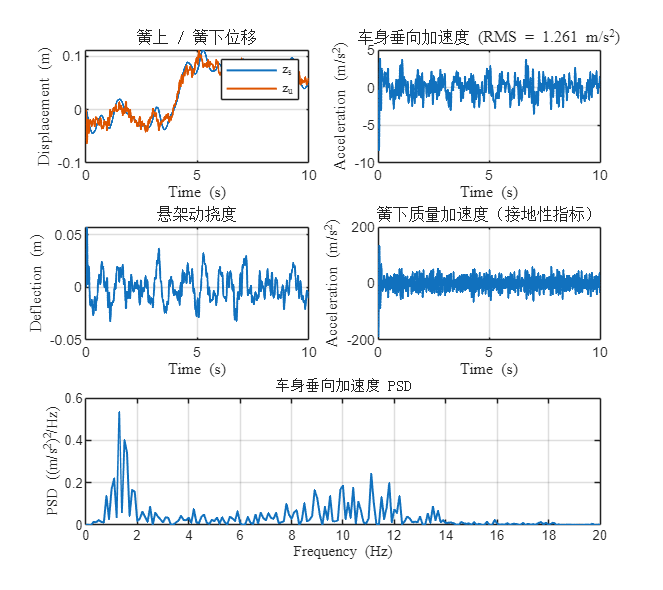


%% ===== 4. 频域分析（舒适性频段） =====
% FFT
Zs_acc_f = fft(zs_ddot);
f = (0:N-1)' * fs / N;

PSD_zs = (abs(Zs_acc_f).^2) / (fs * N);

% 单边谱
idx = 1:floor(N/2);
f1  = f(idx);
PSD1 = PSD_zs(idx);

%% ===== 5. 绘图（中宋体 / 西文 Times New Roman） =====
figure('Name','2-DOF Suspension Analysis','Position',[100 100 900 800])

subplot(3,2,1)
plot(t, zs, 'LineWidth',1.2); hold on;
plot(t, zu, 'LineWidth',1.2);
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Displacement (m)')
legend({ ...
    '\fontname{Times New Roman}z_s', ...
    '\fontname{Times New Roman}z_u'}, ...
    'Interpreter','tex')
title('\fontname{宋体}簧上 / 簧下位移')
grid on

subplot(3,2,2)
plot(t, zs_ddot, 'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Acceleration (m/s^2)')
title(['\fontname{宋体}车身垂向加速度 ', ...
       '\fontname{Times New Roman}(RMS = ', ...
       num2str(az_rms,'%.3f'), ...
       ' m/s^2)'])
grid on

subplot(3,2,3)
plot(t, susp_defl, 'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Deflection (m)')
title('\fontname{宋体}悬架动挠度')
grid on

subplot(3,2,4)
plot(t, zu_ddot, 'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Acceleration (m/s^2)')
title('\fontname{宋体}簧下质量加速度（接地性指标）')
grid on

subplot(3,2,[5 6])
plot(f1, PSD1, 'LineWidth',1.2)
xlim([0 20])
xlabel('\fontname{Times New Roman}Frequency (Hz)')
ylabel('\fontname{Times New Roman}PSD ((m/s^2)^2/Hz)')
title('\fontname{宋体}车身垂向加速度 PSD')
grid on

exportgraphics(gcf, fullfile('plots\', 'Suspension_2DOF分析.png'), 'Resolution', 600);

## 4-DOF Half-Car Suspension Analysis

% 状态变量：
% zs, zs_dot        - 簧上质量垂向位移及速度
% theta, theta_dot  - 车身俯仰角及角速度
% zuf, zuf_dot      - 前轴簧下质量垂向位移及速度
% zur, zur_dot      - 后轴簧下质量垂向位移及速度

clc;
simout = sim("suspension4DOF.slx")

simout =   Simulink.SimulationOutput:

                  theta: [10001x1 double] 
              theta_dot: [10001x1 double] 
                   tout: [10001x1 double] 
                     zs: [10001x1 double] 
                 zs_dot: [10001x1 double] 
                    zuf: [10001x1 double] 
                zuf_dot: [10001x1 double] 
                    zur: [10001x1 double] 
                zur_dot: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t = simout.tout;
zuf = simout.zuf;
zur = simout.zur;
zs = simout.zs;
theta = simout.theta;
zuf_dot = simout.zuf_dot;
zur_dot = simout.zur_dot;
zs_dot = simout.zs_dot;
theta_dot = simout.theta_dot;

%% ===== 基本参数 =====
dt = t(2) - t(1);
fs = 1 / dt;
N  = length(t);

% 字体宏（强烈推荐）
cn = '\fontname{宋体}';
en = '\fontname{Times New Roman}';

%% ===== 1. 派生物理量 =====
% 加速度
zs_ddot    = gradient(zs_dot, dt);
theta_ddot = gradient(theta_dot, dt);
zuf_ddot   = gradient(zuf_dot, dt);
zur_ddot   = gradient(zur_dot, dt);

% RMS 指标
az_rms      = sqrt(mean(zs_ddot.^2));
theta_rms   = sqrt(mean(theta.^2));
theta_dd_rms= sqrt(mean(theta_ddot.^2));

fprintf('簧上质量垂向加速度 RMS = %.4f m/s^2\n', az_rms);

簧上质量垂向加速度 RMS = 1.0465 m/s^2


fprintf('车身俯仰角 RMS = %.4e rad\n', theta_rms);

车身俯仰角 RMS = 3.7410e-03 rad


fprintf('车身俯仰角加速度 RMS = %.4e rad/s^2\n', theta_dd_rms);

车身俯仰角加速度 RMS = 6.9045e-01 rad/s^2



%% ===== 2. 前后轴悬架动挠度（相对位移）=====
susp_defl_f = zs - zuf;   % 前悬
susp_defl_r = zs - zur;   % 后悬

defl_f_rms = sqrt(mean(susp_defl_f.^2));
defl_r_rms = sqrt(mean(susp_defl_r.^2));

fprintf('前悬架动挠度 RMS = %.4f m\n', defl_f_rms);

前悬架动挠度 RMS = 0.0132 m


fprintf('后悬架动挠度 RMS = %.4f m\n', defl_r_rms);

后悬架动挠度 RMS = 0.0096 m


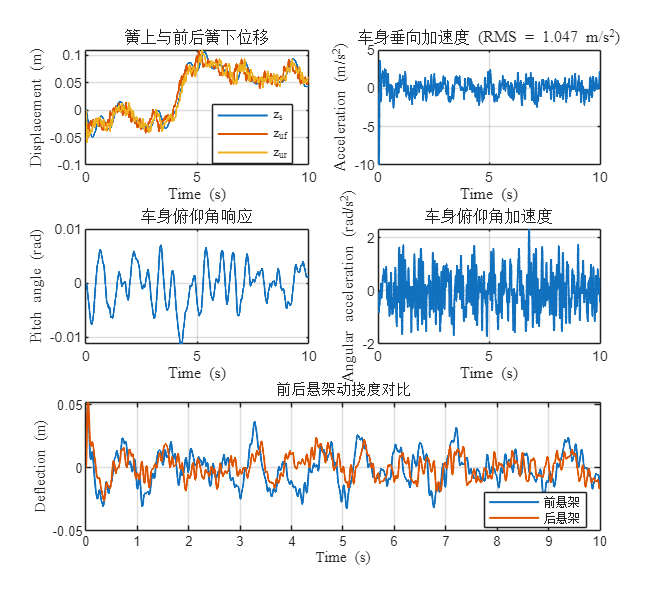


%% ===== 3. 频域分析（车身垂向加速度）=====
Zs_acc_f = fft(zs_ddot);
f = (0:N-1)' * fs / N;
PSD = (abs(Zs_acc_f).^2) / (fs * N);

idx = 1:floor(N/2);
f1  = f(idx);
PSD1 = PSD(idx);

%% ===== 4. 绘图 =====
fig = figure('Name','4-DOF Suspension Analysis',...
             'Position',[100 100 1000 900]);

% --- (1) 簧上 / 簧下位移 ---
subplot(3,2,1)
plot(t, zs, 'LineWidth',1.2); hold on;
plot(t, zuf,'LineWidth',1.2);
plot(t, zur,'LineWidth',1.2);
xlabel([en 'Time (s)'])
ylabel([en 'Displacement (m)'])
legend({ ...
    [en 'z_s'], ...
    [en 'z_{uf}'], ...
    [en 'z_{ur}']}, ...
    'Interpreter','tex','Location','best')
title([cn '簧上与前后簧下位移'])
grid on

% --- (2) 车身垂向加速度 ---
subplot(3,2,2)
plot(t, zs_ddot, 'LineWidth',1.2)
xlabel([en 'Time (s)'])
ylabel([en 'Acceleration (m/s^2)'])
title([cn '车身垂向加速度 ' ...
       en '(RMS = ' num2str(az_rms,'%.3f') ' m/s^2)'])
grid on

% --- (3) 俯仰角 ---
subplot(3,2,3)
plot(t, theta, 'LineWidth',1.2)
xlabel([en 'Time (s)'])
ylabel([en 'Pitch angle (rad)'])
title([cn '车身俯仰角响应'])
grid on

% --- (4) 俯仰角加速度 ---
subplot(3,2,4)
plot(t, theta_ddot, 'LineWidth',1.2)
xlabel([en 'Time (s)'])
ylabel([en 'Angular acceleration (rad/s^2)'])
title([cn '车身俯仰角加速度'])
grid on

% --- (5) 前后悬架动挠度 ---
subplot(3,2,[5 6])
plot(t, susp_defl_f,'LineWidth',1.2); hold on;
plot(t, susp_defl_r,'LineWidth',1.2);
xlabel([en 'Time (s)'])
ylabel([en 'Deflection (m)'])
legend({ ...
    [cn '前悬架'], ...
    [cn '后悬架']}, ...
    'Interpreter','tex','Location','best')
title([cn '前后悬架动挠度对比'])
grid on

%% ===== 5. 导出图片（论文级）=====
exportgraphics(fig,'plots\Suspension_4DOF分析.png','Resolution',600);

## 7-DOF Car Suspension Analysis


clc;
simout = sim("suspension7DOF.slx")

simout =   Simulink.SimulationOutput:

                    Phi: [10001x1 double] 
               Phi_ddot: [10001x1 double] 
                Phi_dot: [10001x1 double] 
                  theta: [10001x1 double] 
             theta_ddot: [10001x1 double] 
              theta_dot: [10001x1 double] 
                   tout: [10001x1 double] 
                     zs: [10001x1 double] 
                zs_ddot: [10001x1 double] 
                 zs_dot: [10001x1 double] 
                   zufl: [10001x1 double] 
              zufl_ddot: [10001x1 double] 
               zufl_dot: [10001x1 double] 
                   zufr: [10001x1 double] 
              zufr_ddot: [10001x1 double] 
               zufr_dot: [10001x1 double] 
                   zurl: [10001x1 double] 
              zurl_ddot: [10001x1 double] 
               zurl_dot: [10001x1 double] 
                   zurr: [10001x1 double] 
              zurr_ddot: [10001x1 double] 
     

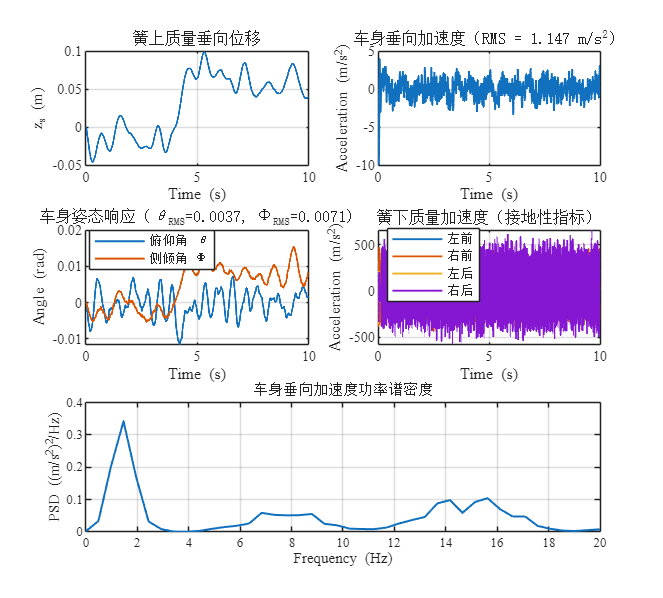

t = simout.tout;
zufl = simout.zufl;
zufr = simout.zufr;
zurl = simout.zurl;
zurr = simout.zurr;
zs = simout.zs;
theta = simout.theta;
Phi = simout.Phi;
zufl_dot = simout.zufl_dot;
zufr_dot = simout.zufr_dot;
zurl_dot = simout.zurl_dot;
zurr_dot = simout.zurr_dot;
zs_dot = simout.zs_dot;
theta_dot = simout.theta_dot;
Phi_dot = simout.Phi_dot;
zufl_ddot = simout.zufl_ddot;
zufr_ddot = simout.zufr_ddot;
zurl_ddot = simout.zurl_ddot;
zurr_ddot = simout.zurr_ddot;
zs_ddot = simout.zs_ddot;
theta_ddot = simout.theta_ddot;
Phi_ddot   = simout.Phi_ddot;

%% ===== 1. 基本设置 =====
dt = t(2) - t(1);
fs = 1/dt;

% 字体设置
fontCN = '宋体';
fontEN = 'Times New Roman';


%% ===== 3. RMS 指标 =====
az_rms     = rms(zs_ddot);
theta_rms  = rms(theta);
phi_rms    = rms(Phi);

%% ===== 4. PSD（车身垂向加速度）=====
[PSD_zs, f] = pwelch(zs_ddot, hamming(2048), 1024, 2048, fs);

%% ===== 5. 绘图 =====
fig = figure('Name','7DOF Suspension Analysis',...
    'Position',[100 100 1000 900]);

%% --- (1) 簧上垂向位移 ---
subplot(3,2,1)
plot(t, zs, 'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}z_s (m)')
title('\fontname{宋体}簧上质量垂向位移')
grid on

%% --- (2) 车身垂向加速度 ---
subplot(3,2,2)
plot(t, zs_ddot, 'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Acceleration (m/s^2)')
title(['\fontname{宋体}车身垂向加速度（RMS = ', ...
       num2str(az_rms,'%.3f'), ' m/s^2）'])
grid on

%% --- (3) 俯仰 / 侧倾角 ---
subplot(3,2,3)
plot(t, theta, 'LineWidth',1.2); hold on
plot(t, Phi,   'LineWidth',1.2)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Angle (rad)')
legend({'\fontname{宋体}俯仰角 \theta',...
        '\fontname{宋体}侧倾角 \Phi'},...
        'Location','best')
title(['\fontname{宋体}车身姿态响应（\theta_{RMS}=',...
       num2str(theta_rms,'%.4f'),...
       ', \Phi_{RMS}=',num2str(phi_rms,'%.4f'),')'])
grid on

%% --- (4) 四轮簧下加速度（接地性） ---
subplot(3,2,4)
plot(t, zufl_ddot,'LineWidth',1.1); hold on
plot(t, zufr_ddot,'LineWidth',1.1)
plot(t, zurl_ddot,'LineWidth',1.1)
plot(t, zurr_ddot,'LineWidth',1.1)
xlabel('\fontname{Times New Roman}Time (s)')
ylabel('\fontname{Times New Roman}Acceleration (m/s^2)')
legend({'\fontname{宋体}左前',...
        '\fontname{宋体}右前',...
        '\fontname{宋体}左后',...
        '\fontname{宋体}右后'},...
        'Location','best')
title('\fontname{宋体}簧下质量加速度（接地性指标）')
grid on

%% --- (5) PSD ---
subplot(3,2,[5 6])
plot(f, PSD_zs, 'LineWidth',1.2)
xlim([0 20])
xlabel('\fontname{Times New Roman}Frequency (Hz)')
ylabel('\fontname{Times New Roman}PSD ((m/s^2)^2/Hz)')
title('\fontname{宋体}车身垂向加速度功率谱密度')
grid on

%% ===== 6. 全局字体修正 =====
set(findall(fig,'-property','FontName'),'FontName',fontEN)
set(findall(fig,'Type','text'),'FontName',fontCN)

%% ===== 7. 高分辨率导出 =====
exportgraphics(fig,'plots\Suspension_7DOF分析.png','Resolution',600);